clear all; close all
load('Measurement_performance_v7.mat')
e = measurement_performance_v7(:,1);
y = measurement_performance_v7(:,2);

fs = 4000

fs = 4000


%removing bad data

N_trash = 5e3; 
e = e(N_trash:end);
y = y(N_trash:end);
v = [0; diff(y)]; %computing velocity with padding
a = [0; diff(v)]; %computing acceleration 
L = length(e); %data length
t = [0:1/fs:L/fs-1/fs]; %time variable


rms(e)*1e3

ans = 8.3079

max(abs(e))*1e3

ans = 122.5221

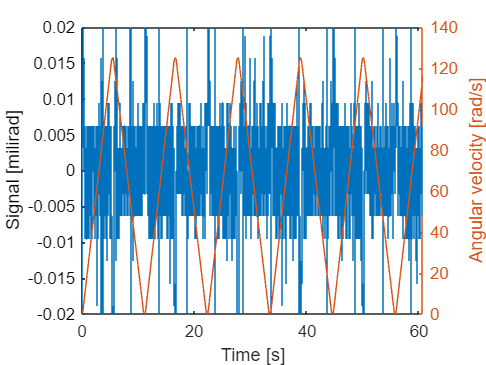


max_value = 20e-3;
e(e>max_value) = max_value;
e(e<-max_value) = -max_value;

figure();
stairs(t,e);
xlabel('Time [s]'); ylabel('Signal [milirad]');

%adding limits
limits = 20e-3;
ylim([-limits,limits])

%plotting velocity 
yyaxis right
plot(t,y)
ylabel('Angular velocity [rad/s]')

%adding limits
limits = 0.05;
%ylim([-limits,limits])
hold off

%removing data with acceleration
%removing data without constant velocity
and(y>5,y <120)

ans = 243001×1 logical array
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



e_filtered = e(and(y>20,y <100)) 

e_filtered =     0.0031
    0.0031
    0.0031
    0.0031
         0
         0
         0
    0.0031
    0.0031
    0.0031


max_value = 20e-3;
e_filtered(e_filtered>max_value) = max_value;
e_filtered(e_filtered<-max_value) = -max_value;
%e_filtered = e_filtered(y<122.5)
rms(e_filtered)*1e3

ans = 3.9871

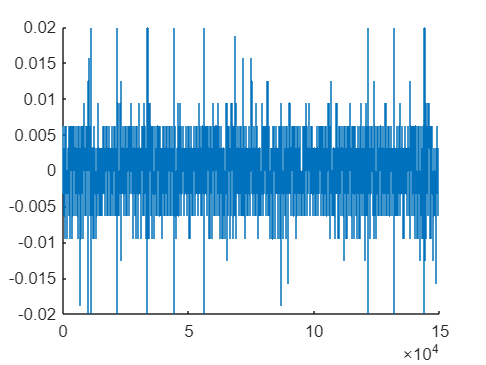

figure()
hold on
stairs(e_filtered)
%adding limits
limits = max_value;
ylim([-limits,limits])
hold off

%data analysis
fs = 4000 %[Hz]

fs = 4000

stepsize = 1/fs %[s]

stepsize = 2.5000e-04

max_freq = log10(fs/2) 

max_freq = 3.3010



%window settings
min_freq = 0.1; %[Hz/s] lowest desired sampling frequency
windowsize = 1/min_freq; %[s] window size in seconds

nfft = round(windowsize*fs) %window size in data points 

nfft = 40000

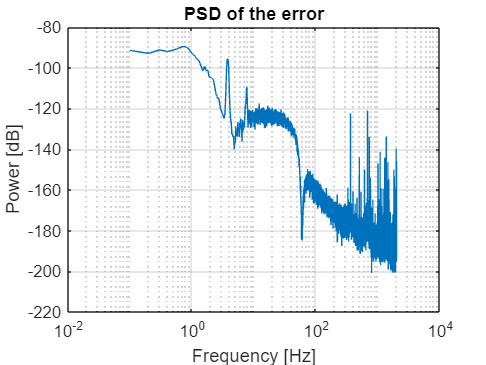

n_overlap = round(nfft/3);

%Tf estimate
[psd_e, F] = pwelch(e,hann(nfft),n_overlap,nfft,fs,'psd'); %spectral power disturbance

figure()
semilogx(F,mag2db(abs(psd_e)))
title("PSD of the error")
xlabel('Frequency [Hz]')
ylabel('Power [dB]')
grid on; hold off